# GMM

clear;clc;

gauss = @(x,mu,sigma) (1/((2*pi)^size(x,1)*det(sigma))^0.5)*exp(-0.5*(x-mu)'*(sigma\(x-mu)));

## Data Preparation

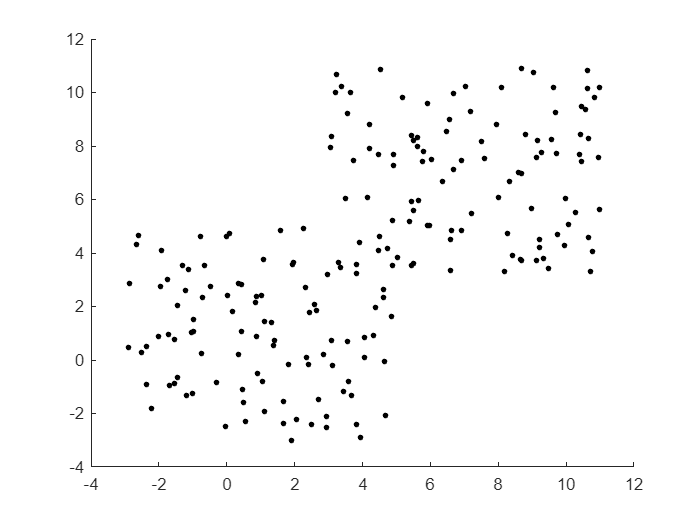

var = 8;
data1 = rand(100,2)*var + 3;
data2 = rand(100,2)*var - 3;
X_train = [data1; data2];
figure;
hold on;
for j=1:size(X_train,1)
    plot(X_train(j,1),X_train(j,2),'.','Color','black','MarkerSize',10)
end
hold off;

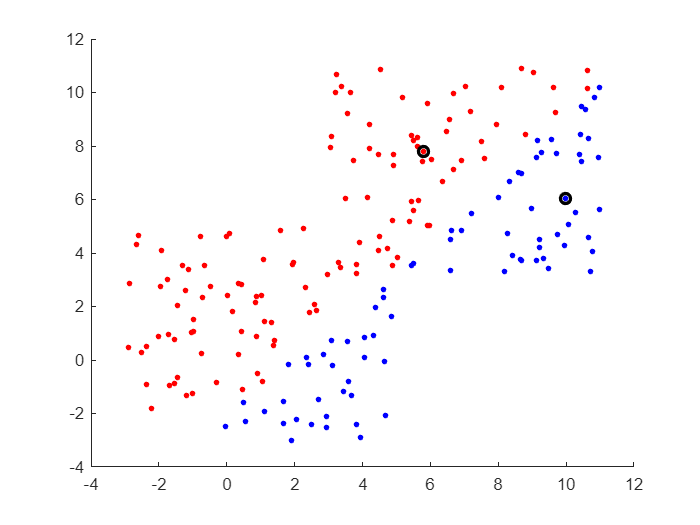

D = size(X_train,2);
K = 2;
mu = rand(K,size(X_train,2));
for i=1:K
    r = round(size(X_train,1)*rand(1,1));
    if r==0
        r = r+1;
    end  
    mu(i,:) = X_train(r,:);
end
sigma = zeros(K,D,D);
sigma(1,:,:) = cov(X_train);
sigma(2,:,:) = cov(X_train);
pi_k = [0.5;0.5];
gznk = gamma_znk(X_train,pi_k,mu,sigma,gauss);
N_k = sum(gznk,1)';

figure;
hold on;
for j=1:size(X_train,1)
    if gznk(j,1)>gznk(j,2)
        plot(X_train(j,1),X_train(j,2),'.','Color','blue','MarkerSize',10)
    else
        plot(X_train(j,1),X_train(j,2),'.','Color','red','MarkerSize',10)
    end
end
plot(mu(1,1),mu(1,2),'o','Color','black','LineWidth',2);
plot(mu(2,1),mu(2,2),'o','Color','black','LineWidth',2);
hold off;

## EM Algorithm

LL = log_liklihood(X_train,pi_k,mu,sigma,gauss);
prev_LL = 0;
while(abs(prev_LL-LL) > 1e-5)
    prev_LL = LL;
    for k=1:K
        temp_m = 0;        
        for i=1:size(X_train,1)
            temp_m = temp_m + gznk(i,k) * X_train(i,:);
        end
        mu(k,:) = temp_m/N_k(k);
        temp_s = 0;
        for i=1:size(X_train,1)
            temp_s = temp_s + gznk(i,k) * (X_train(i,:)-mu(k,:))'*(X_train(i,:)-mu(k,:));
        end
        sigma(k,:,:) = temp_s/N_k(k);
    end
    gznk = gamma_znk(X_train,pi_k,mu,sigma,gauss);
    N_k = sum(gznk,1)';
    pi_k = N_k/sum(N_k);
    LL = log_liklihood(X_train,pi_k,mu,sigma,gauss);    
%     disp(LL);
end

## Plot

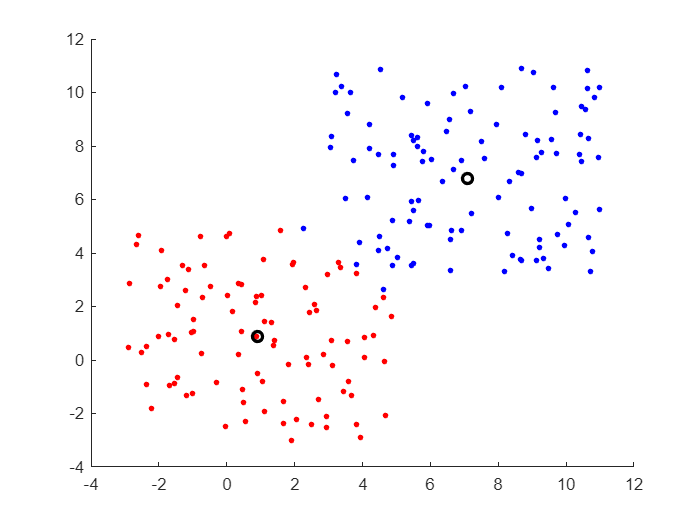

figure;
hold on;
for j=1:size(X_train,1)
    if gznk(j,1)>gznk(j,2)
        plot(X_train(j,1),X_train(j,2),'.','Color','blue','MarkerSize',10)
    else
        plot(X_train(j,1),X_train(j,2),'.','Color','red','MarkerSize',10)
    end
end
plot(mu(1,1),mu(1,2),'o','Color','black','LineWidth',2);
plot(mu(2,1),mu(2,2),'o','Color','black','LineWidth',2);
hold off;

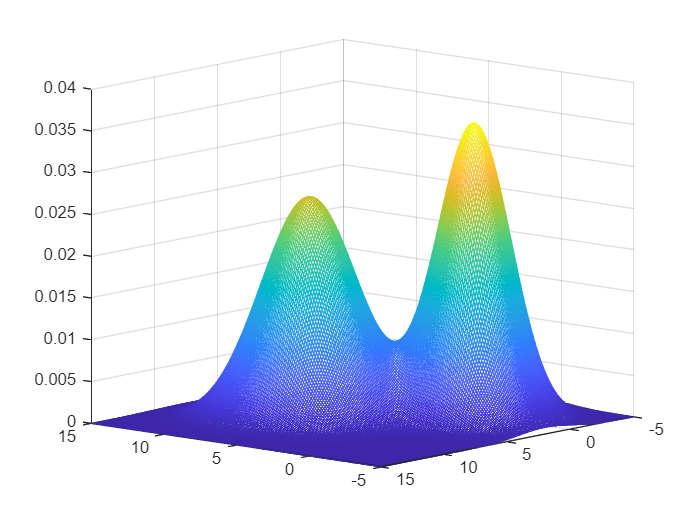

[x,y] = meshgrid(-5:.1:15);
z = zeros(size(x));
for i=1:size(z,1)
    for j=1:size(z,2)
        q = [x(i,j);y(i,j)];
        z(i,j) = gauss(q,mu(1,:)',squeeze(sigma(1,:,:))) + gauss(q,mu(2,:)',squeeze(sigma(2,:,:)));
    end
end
figure;
mesh(x,y,z);

function value = gamma_znk(X_train,pi_k,mu,sigma,fun)
    value = zeros(size(X_train,1),size(pi_k,1));
    for i=1:size(X_train,1)
        temp = 0;
        for k=1:size(pi_k,1)
            value(i,k) = pi_k(k) * fun(X_train(i,:)',mu(k,:)',squeeze(sigma(k,:,:)));
            temp = temp + value(i,k);
        end
        value(i,:) = value(i,:) / temp;
    end
end

function value = log_liklihood(X_train,pi_k,mu,sigma,fun)
    value = 0;
    for i=1:size(X_train,1)
        temp = 0;
        for k=1:size(pi_k,1)
            temp = temp + pi_k(k) * fun(X_train(i,:)',mu(k,:)',squeeze(sigma(k,:,:)));
        end
        value = value + log(temp);
    end
    value = -value;
end